% BMED 7610 HW 2 

clear
close all hidden
% read matrix file
cortical_spikes = load('HWK2_prob1A_data.mat','-mat','spike_times');

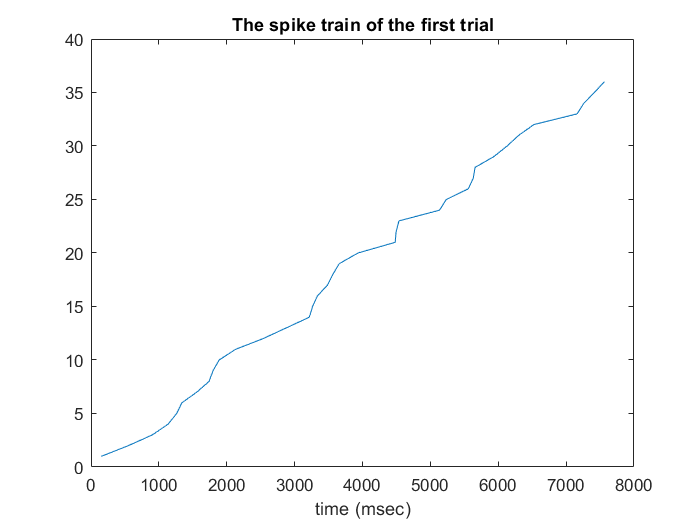

% a) plot the spike train of the first trial
spk_times = cortical_spikes.spike_times;
plot(spk_times(1, :), 1:36)
title('The spike train of the first trial')
xlabel('time (msec)')

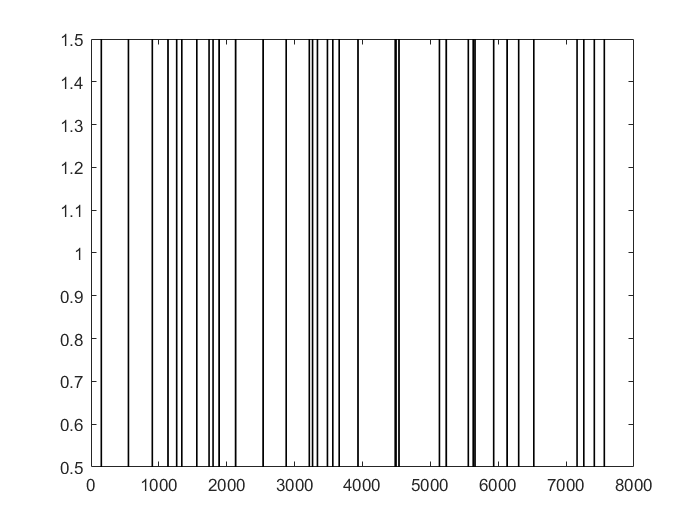

% b) a raster plot of all the trials

x = spk_times(1, :);
y = ones([1 36]);
plot_raster(x, y);

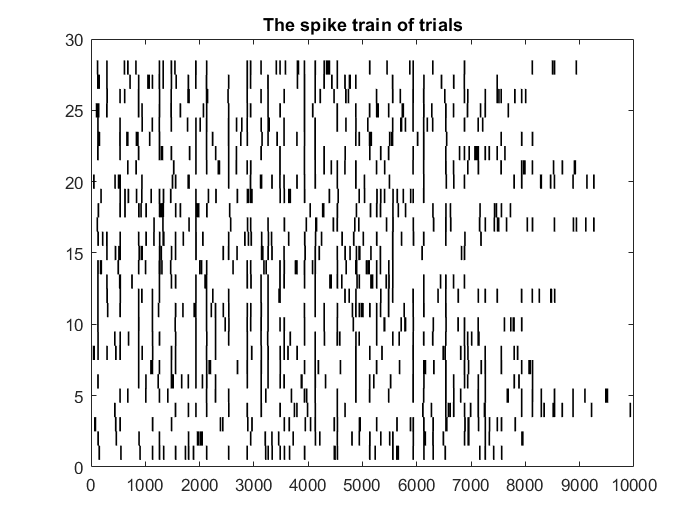

hold on
for trial = 1:28
    x = spk_times(trial, :);
    y = trial*ones([1 36]);
    plot_raster(x, y);
end
hold off
title('The spike train of trials')

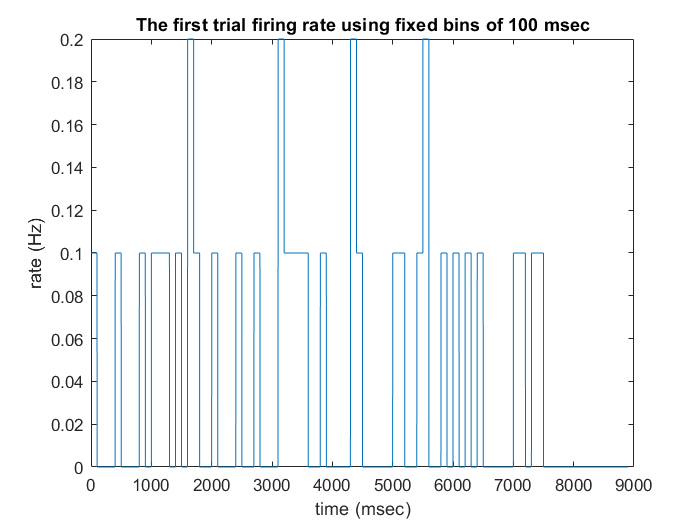

% c) calculate firing rate of the first trial using fixed bins of 100 msec

firing_rate = zeros([1 8900]);
num_spikes = zeros([1 8900]);
for time = 100:8900
%     disp(time);
    num_spikes(time) = sum(spk_times(1, :)>time & spk_times(1, :)<(time+100));
    firing_rate(time) = num_spikes(time)/100;
    if mod(time, 100) == 0
%         disp(time);
        num_spikes(time-99:time)= num_spikes(time);
        firing_rate(time-99:time) = firing_rate(time);
        time = time + 100;
        
    end
    
end
% firing_rate = num_spikes/spk_times(1, -1);
t = 1:8900;
firing_rate = firing_rate*10; %converting to Hz
% stem(t, firing_rate)
plot(t, firing_rate);
title('The first trial firing rate using fixed bins of 100 msec')
xlabel('time (msec)')
ylabel('rate (Hz)')

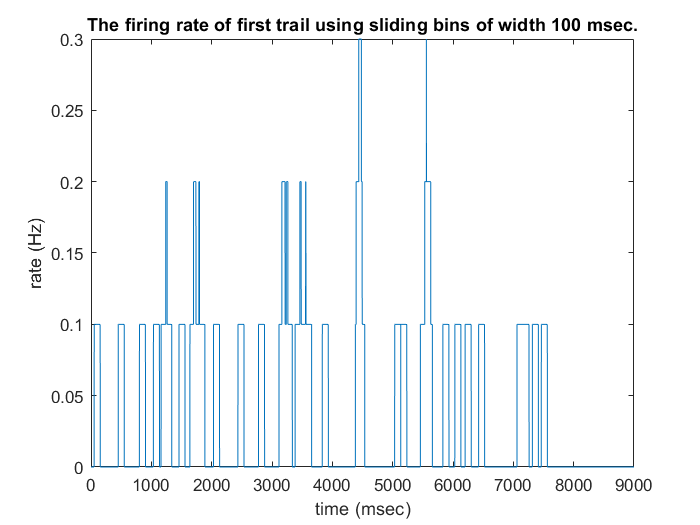

% d) Calculate firing rate of the first trial using a sliding rectangular bin of 100 msec

firing_rate_sliding = zeros([1 9000]);
num_spikes_sliding = zeros([1 9000]);
for time=1:8900
    num_spikes_sliding(time)=sum(spk_times(1, :)>time & spk_times(1, :)<(time+100));
    firing_rate_sliding(time) = num_spikes_sliding(time)/100;
end
t = 1:9000;
firing_rate_sliding = firing_rate_sliding*10; %converting to Hz
plot(t, firing_rate_sliding)
title('The firing rate of first trail using sliding bins of width 100 msec.')
xlabel('time (msec)')
ylabel('rate (Hz)')

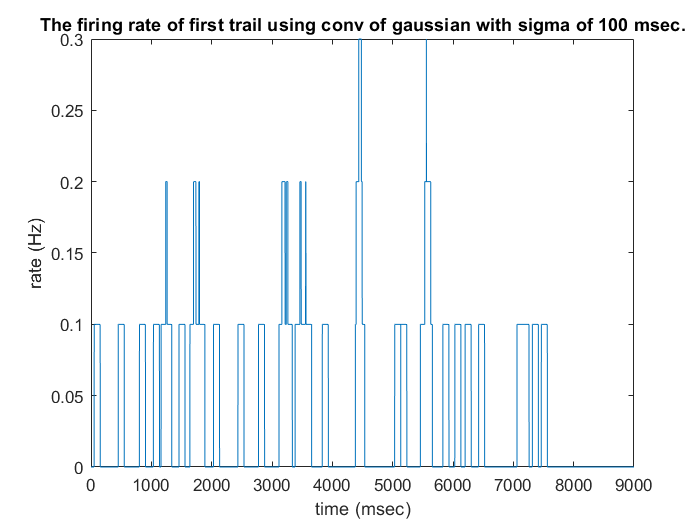

% e) Calculate firing rate of the first trial by convolution of a gaussian window of width sigma = 100 msec
width = 100;

g = linspace(0,width, 100);
gaus_f = gauss(width, 1);
% plot(g, gaus_f);

firing_rate_gaus = zeros([1 9000]);
num_spikes_gaus = zeros([1 9000]);
num_spikes = zeros([1 100]);
dx = g(2)-g(1);
for time = 1:9000
    num_spikes(time:time+99)= sum(spk_times(1, :)>time & spk_times(1, :)<(time+100));
    num_spikes_gaus(time:time+198) = conv(num_spikes(time:time+99),gaus_f)*dx;
    firing_rate_gaus(time) = num_spikes_sliding(time)/100;
end
t = 1:9000;
firing_rate_gaus = firing_rate_gaus*10; %converting to Hz
plot(t, firing_rate_gaus)
title('The firing rate of first trail using conv of gaussian with sigma of 100 msec.')
xlabel('time (msec)')
ylabel('rate (Hz)')